# **Task 4: Compare maps for control and pre-eclampsia participants**

Author: Yu Fu and Simon Ellershaw

**Preprocessing**

% load data

% Init objects
model = T2ADCModel();
non_lin_optimiser = NonLinearOptimiser();

num_scans = length(grad_echo);
% Compute ROI 
ROI_healthy_placenta_uterine_wall = zeros(size(V_healthy));
ROI_healthy_placenta = zeros(size(V_healthy));
ROI_pre_eclampsia_placenta_uterine_wall = zeros(size(V_pre_eclampsia));
ROI_pre_eclampsia_placenta = zeros(size(V_pre_eclampsia));
for i = 1:num_scans
    % with uterine_wall
    ROI_healthy_placenta_uterine_wall(:,:,:,i) = V_healthy(:,:,:,i).*M_healthy_placenta_uterine_wall;
    ROI_pre_eclampsia_placenta_uterine_wall(:,:,:,i) = V_pre_eclampsia(:,:,:,i).*M_pre_eclampsia_placenta_uterine_wall;
    
    % only placenta
    ROI_healthy_placenta(:,:,:,i) = V_healthy(:,:,:,i).*M_healthy_placenta;
    ROI_pre_eclampsia_placenta(:,:,:,i) = V_pre_eclampsia(:,:,:,i).*M_pre_eclampsia_placenta;
end

% Data preprocessing for fitting
num_loops = 5; % Set based of previous experiments
bvals = grad_echo(:, 4);
TE = grad_echo(:, 5);
% Constrained voxel multi run fit
pertubation_sigmas_constr_space = T2ADCModel.to_constr_space([50 0.01 0.001]);
% start parameters
start_params = [100 0.01 0.001];
start_params_constr_space = T2ADCModel.to_constr_space(start_params);


**Slice 7 (in both scans) is a good place to start as it has good coverage of the placenta**

% [height, width, TE]
slice_7_healthy_placenta = squeeze(ROI_healthy_placenta(:,:,7,:)); 
slice_7_healthy_placenta_uterine_wall = squeeze(ROI_healthy_placenta_uterine_wall(:,:,7,:));
slice_7_pre_eclampsia_placenta = squeeze(ROI_pre_eclampsia_placenta(:,:,7,:));
slice_7_pre_eclampsia_placenta_uterine_wall = squeeze(ROI_pre_eclampsia_placenta_uterine_wall(:,:,7,:));

**Run the fit**

% healthy placenta
[parameter_map_hc, best_SSD_map_hc] = non_lin_optimiser.slice_multi_run(model, slice_7_healthy_placenta, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200


% healthy placenta with uterine wall 
[parameter_map_hcuw, best_SSD_map_hcuw] = non_lin_optimiser.slice_multi_run(model, slice_7_healthy_placenta_uterine_wall, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200


% pre-eclampsia placenta
[parameter_map_pe, best_SSD_map_pe] = non_lin_optimiser.slice_multi_run(model, slice_7_pre_eclampsia_placenta, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200


% pre-eclampsia placenta with uterine wall 
[parameter_map_peuw, best_SSD_map_peuw] = non_lin_optimiser.slice_multi_run(model, slice_7_pre_eclampsia_placenta_uterine_wall, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

**Plot Parameters maps**

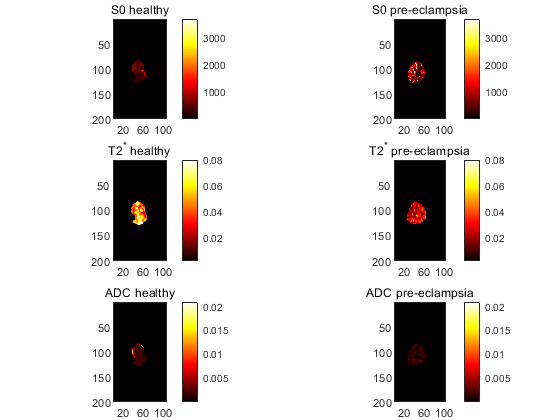

figure(1);
Task4_PlotVoxelwiseMaps(parameter_map_hc, parameter_map_pe);

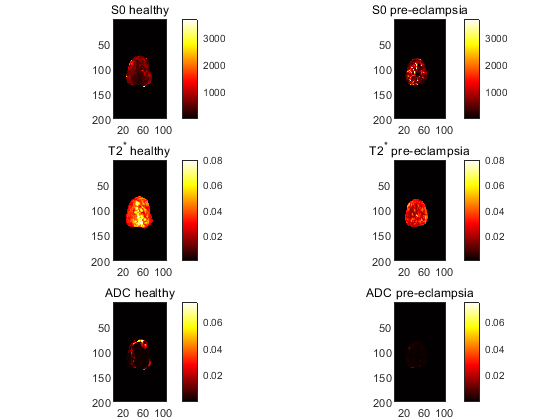

figure(2);
Task4_PlotVoxelwiseMaps(parameter_map_hcuw, parameter_map_peuw);

**Plot the boxplots to show how the parameter values within ROIs differ**

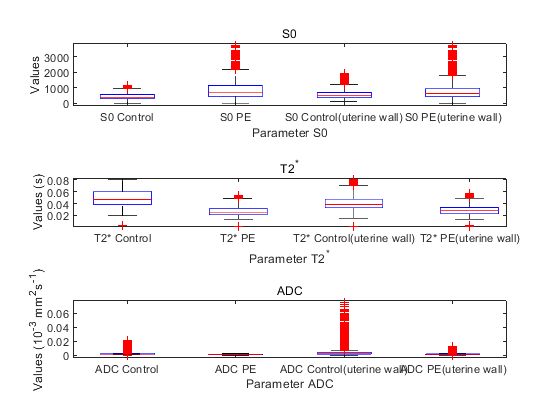

figure(3);
Task4_PlotBoxplots(parameter_map_hc, parameter_map_pe, parameter_map_hcuw, parameter_map_peuw); 

Remove the ourliers of ADC?

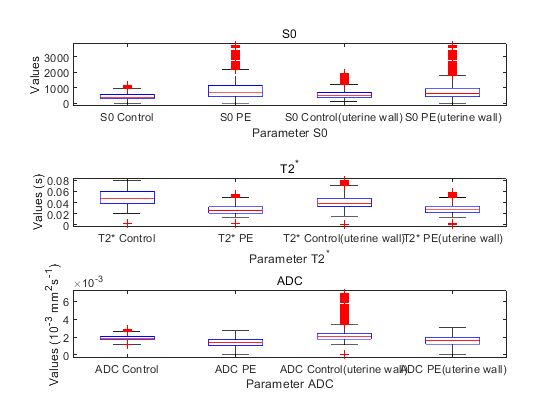

figure(4);
Task4_PlotBoxplots(parameter_map_hc, parameter_map_pe, parameter_map_hcuw, parameter_map_peuw); 

Plot the Parameters maps with the original voxel b = 0 (s/mm^-2) , lowest TE = 78 (ms), replace 0 in the parameters (black area)

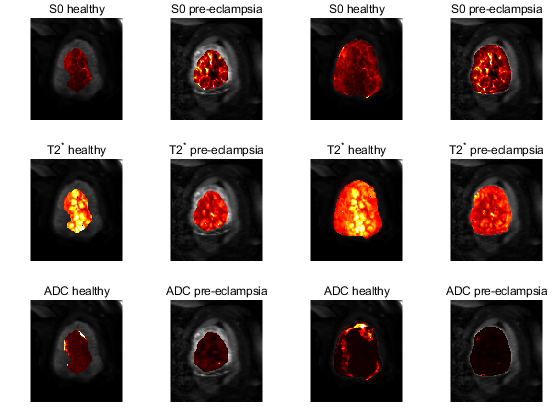

figure(5);
Task4_PlotMapsWithData(parameter_map_hc, parameter_map_pe, parameter_map_hcuw, parameter_map_peuw, V_healthy, V_pre_eclampsia)